# ENGR 845 Mini Project Assignment: Human Activity Classification Using Smartphone Data 

The purpose of this assignment is for the students to gain hands-on experience with the concepts taught in the class including human data processing, feature engineering, pattern classification, and parameter tuning.

References: 

- iLearn -> Reference Materials-> Adding Machine Learning to Signal Processing Application

- iLearn -> Reference Materials-> Collect Accelerometer Data from Smartphone (For Use in Matlab)

- iLearn -> Software Materials-> EMG PR code 2.0 (updated on 3/13/2019)

- iLearn -> Lecture Slides -> ENGR845 Lecture4 EMG Pattern Recognition Feature Engineering

Please read the instructions below and complete the required fields marked with an *. 

## Data Collection

In this assignment, 3-axis acceleration data from an *Android or iOS smartphone (*please complete with the device OS and model*) for **at least three** different classes of human activities (e.g. sitting, standing, walking, running, dancing, riding bicycle, jumping, falling, etc.) are collected from yourself. *These motions are (*please complete*)

- Activity 1

- Activity 2

- Activity 3

- ...

*Please describe how the data are collected, including (*please put your answer under each question; images can also be added if needed*)

- Where the device is placed on the body (please make sure for the entire data collection procedure, keep the device in the same place) **Shoulder, each movement was performed for about 1 minute and in sequence with no reset in between them**.

- How many trials are collected for each activity (at least two for each activity)? How long is each trial (at least 5s for each trial)? **1 trial per activity, but each trial was 1 whole minute.**

- What is the sampling frequency for data collection?**   52.63 Hz**

- Please describe the experimental procedure including: how is each trial  started and ended; how is the data saved; for each activity, how does the subject perform the activity in each trial (e.g. walking at a fast/moderate/slow speed for 10s in each *Walking* trial; climb up 8-step stairs at a  fast/moderate/slow speed in each *Stair Ascent* trial). Please be as detailed as possible. ** Data collection was continuous, starting with rest position, standing, walking, running, and dancing. Data is collected using an Android's phone accelerometer with MATLAB Mobile installed.**

- How are the data trials named (e.g. sitting_1.mat, standing_*DateTime.mat*)?**   All of the data is concatenated in a phone_accel.mat file.**

## Dataset Preparation

The dataset is located in the ***root folder of the project** (*please complete*) folder. For each activity class, there are ***one file containing all activities** (*please complete*) files stored in the folder. 

In this assignment, we create two sub-folders ...*/train* (*please complete*) and .../*test* (*please complete*) to partition the dataset into training and testing sets. Specifically, files with names ***none**(*please complete*) are stored in the train folder, while files with names ***none**(*please complete*) are stored in the test folder. **Data is loaded from the phone_accel.mat into the workspace, separated by class, then used to train. It is not divided and saved into their respective folders.**

#### Raw Data at a glance

*Please write MATLAB code to plot some example trials for the activities

% This is just an example, please write your own code in this section to
% plot the raw data you collected
clear all
close all
load('phone_accel.mat')

clear accel labels;
figure
plot(accel_Extracted(:,1),'b');
hold;
plot(labels_Extracted(:,1),'g');
ylim([-30 30]);
title('Blue = accl, Green = label');


*Please add the screenshots of the plotted images (because the instructor will not have time to run all the code segments manually to see the results) below. Don't forget to describe the images using labels, captions, or descriptions.

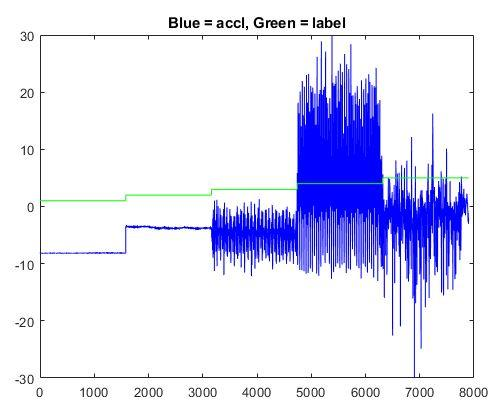

## Feature Extraction

*Please write MATLAB code to extract **at least three** features from the raw data. Please describe how the feature extraction is done, including (*please put your answer under each question; images can also be added if needed*)

- Is the raw data segmented by analysis windows? If so, what are the window length (WL) and window increament (WInc), respectively? You have to try **at least three** different combinations of WL and WInc values and please list the values you have tried. You can also write a program to automatically use a range of WL and WInc values for feature extraction. **The raw data is segmented in the preprocessing stage. The following 3 difference combinations of windows length and increment respectively have been hardcoded: 100/20, 150/20, and 50/10.**

- Which features are extracted and how are they calculated? For each feature, please write down the feature name, formula to calculate the feature, and the MATLAB code to implement the feature calculation.** The features extracted are mean absolute value, zero crossings, and slope changes. They are found by the following functions: meanabs(), dsp.ZeroCrossingDetector, and findpeaks(). For their implementation, see featureExtraction.m.**

- Please write MATLAB code to do feature extraction for both training dataset and testing dataset. For each dataset, the output from this module should be three variables: 

- a *M x N* feature matrix, where N is the number of analysis windows; M is the number of features extracted from each window. For example, if the acceleration data has three axes X, Y, and Z, and four features are extracted from each axis, then the value of M should be three (axes) times four (features), which is 12. **In this case, three axis times three features is 10.**

- a *1 x N* label vector, where N is the number of analysis windows. This vector contains the class label (i.e. index value of the activity) for each window.** Label vector is attached to feature vector. To see it, use "trainFeat_100_20(10, :)".**

- a *(M+1) x N *matrix that combines the feature matrix and the label vector, which is the requried input format for the ***Classification Learner*** app. The first M rows are feature and the last row should be the class label. 

*Please put the MATLAB code in the box below (you can create addtional .m scripts or helper functions if needed):

% Complete code segment for feature extraction
% NOTE: FEATURE EXTRACTION HAPPENS IN featureExtraction.m file!!!
...
percentTrain = 0.70;
numOfClasses = 5;
numOfData = size(accel_Extracted,1);

samplesPerClass = 1580;
start_idx = 1;                        %index through data

% init empty arrays with different of window length and increments
trainFeat_100_20 = []; testFeat_100_20 = [];
trainFeat_150_20 = []; testFeat_150_20 = [];
trainFeat_50_10 = [];  testFeat_50_10 = [];

for itr = 0:numOfClasses-1
    start_idx = itr*samplesPerClass+1;
    end_idx = start_idx+samplesPerClass-1;
    % separate classes
    classData = accel_Extracted(start_idx:end_idx,1:3);
    classLabel= labels_Extracted(start_idx:end_idx,1:1);
    % get 70% of class data for training
    accTrainData   = classData(1:samplesPerClass*percentTrain, :);
    accTrainLabels = classLabel(1:samplesPerClass*percentTrain, :);
    
    % feature extraction for training
    trainFeat_100_20 = [trainFeat_100_20 featureExtraction(accTrainData, accTrainLabels, 100, 20)];
    trainFeat_150_20 = [trainFeat_150_20 featureExtraction(accTrainData, accTrainLabels, 150, 20)];
    trainFeat_50_10 =  [trainFeat_50_10 featureExtraction(accTrainData, accTrainLabels, 50, 10)];
    
    % get 30% of class data for testing
    accTestData    = classData(samplesPerClass*percentTrain+1:end, :);
    accTestLabels  = classLabel(samplesPerClass*percentTrain+1:end, :);
    
    % feature extraction for training
    testFeat_100_20 = [testFeat_100_20 featureExtraction(accTestData, accTestLabels, 100, 20)];
    testFeat_150_20 = [testFeat_150_20 featureExtraction(accTestData, accTestLabels, 150, 20)];
    testFeat_50_10 =  [testFeat_50_10 featureExtraction(accTestData, accTestLabels, 50, 20)];
    
end

% normalization of sets varying wLengths and WIncs
%100_20
[trainFeat_100_20_norm, PS] = mapstd(trainFeat_100_20(1:9,:));
trainFeat_100_20_norm = [trainFeat_100_20_norm; trainFeat_100_20(10, :)];
testFeat_100_20_norm = [mapstd('apply', testFeat_100_20(1:9,:), PS); testFeat_100_20(10,:)];

%100_20
[trainFeat_150_20_norm, PS] = mapstd(trainFeat_150_20(1:9,:));
trainFeat_150_20_norm = [trainFeat_150_20_norm; trainFeat_150_20(10, :)];
testFeat_150_20_norm = [mapstd('apply', testFeat_150_20(1:9,:), PS); testFeat_150_20(10,:)];

%100_20
[trainFeat_50_10_norm, PS] = mapstd(trainFeat_50_10(1:9,:));
trainFeat_50_10_norm = [trainFeat_50_10_norm; trainFeat_50_10(10, :)];
testFeat_50_10_norm = [mapstd('apply', testFeat_50_10(1:9,:), PS); testFeat_50_10(10,:)];


clear percentTrain accel_Extracted labels_Extracted numOfData;

*Please add the screenshots of the generated results (e.g. generated variables in the workspace, content of the feature matrix, image of the plotted feature values) of this section (because the instructor will not have time to run all the code segments manually to see the results) below. **Don't forget to explain the results**.

...

**Generated variables in the workspace. (also includes all trained models)**

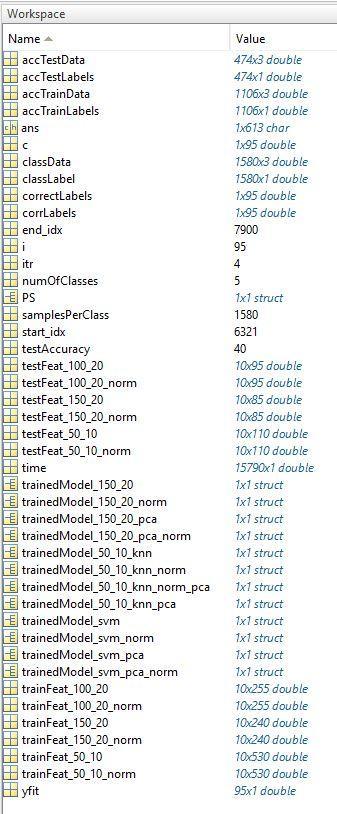

**Content of feature matrix for training set of wl 100 and wi 20.**

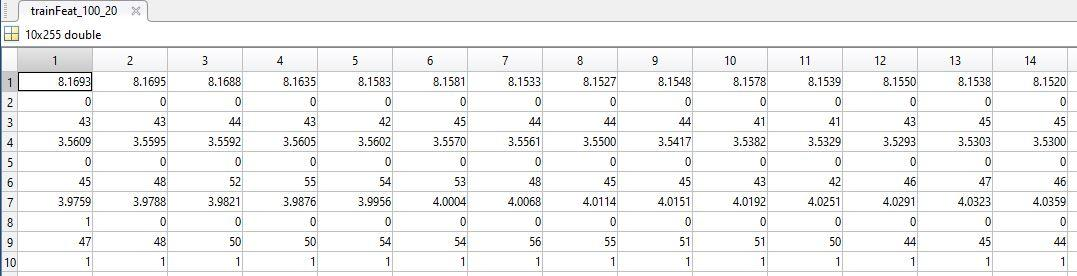

## Classification - Train a Model

Now we can train a classifier model using the feature matrix generated in the previous step. In this assignment, we use the MATLAB built-in ***Classification Learner*** app to do pattern classification. 

You can launch the ***Classification Learner*** app by running the code below or open it from the APPS menu. Please refer to the references provided at the top of this document to learn how to use the app.

%classificationLearner

% Code to test models manually! must change according to name of model.
correctLabels = testFeat_100_20(10,:);
yfit = trainedModel_50_10_knn_norm_pca.predictFcn(testFeat_100_20(1:9,:)) ;

for i = 1:size(testFeat_100_20,2)
    if(yfit(i) == correctLabels(i)); c(i) = 1; else; c(i) = 0; end
end

testAccuracy = (sum(c)/size(c,2))*100

testAccuracy = 40

The Classification Learner requires an input combining the feature variables and the class labels, which should be the third variable generated from your feature extraction code for the training dataset. In this assignment, you are required to conduct several experiments to train classifiers with different combinations of parameters and test them on the testing dataset. You need to try at least three different combinations of WL and WInc values, adding feature normalization/standization or not, adding feature reduction technique (e.g. PCA) or not, and at least two different classification methods. Rembmer, you can only change one parameter at a time, so the combinations could be a lot. 

*You need to report the results in a table using the following suggested format (you can create the table using other software and add the table image here):

**Result table (also available in excel sheet in root dir)**

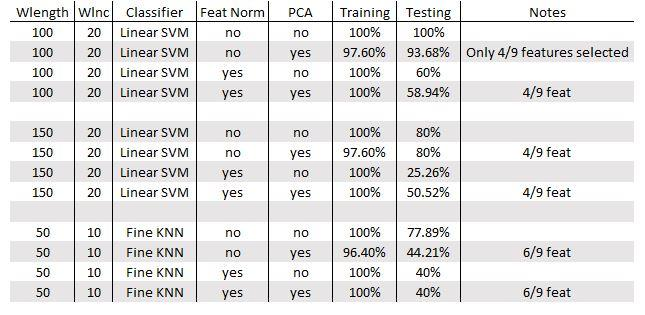

**Note: three different combinations of window length/increments, each with every pca/norm combination. The two classifiers implemented are Linear SVM and Fine KNN.**

*You need to then conclude which parameters yield the best results. 

*In addition,  you need to include the screenshots of your experiemntal procedure of this section (e.g. generated variables in the workspace, screenshot of the ClassifiationLearner app configuration for representative experimental trials) to demonstrate you have done the work by yourself. **Don't forget to explain the screenshots**.

**Inputting the 100/20 no norm set into the Classifier App**

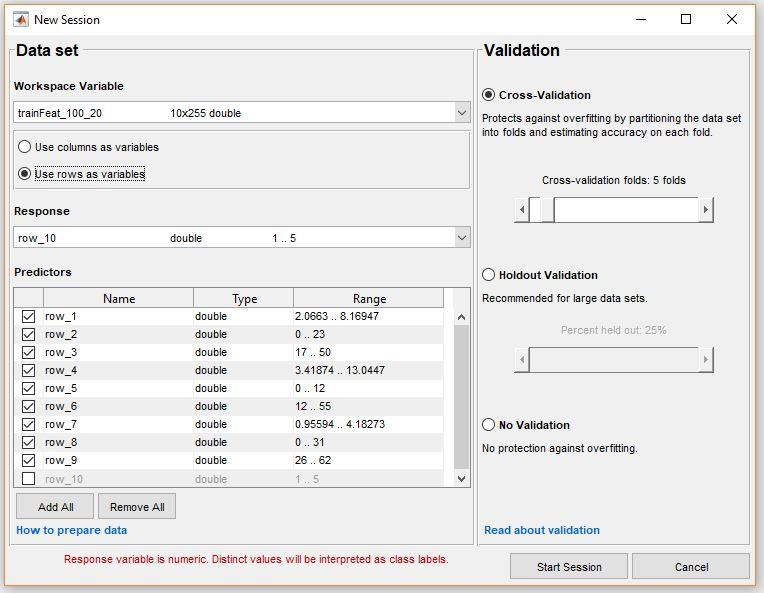

**Feature plot of mean absolute value of the x axis vs zero crossings in x axis**

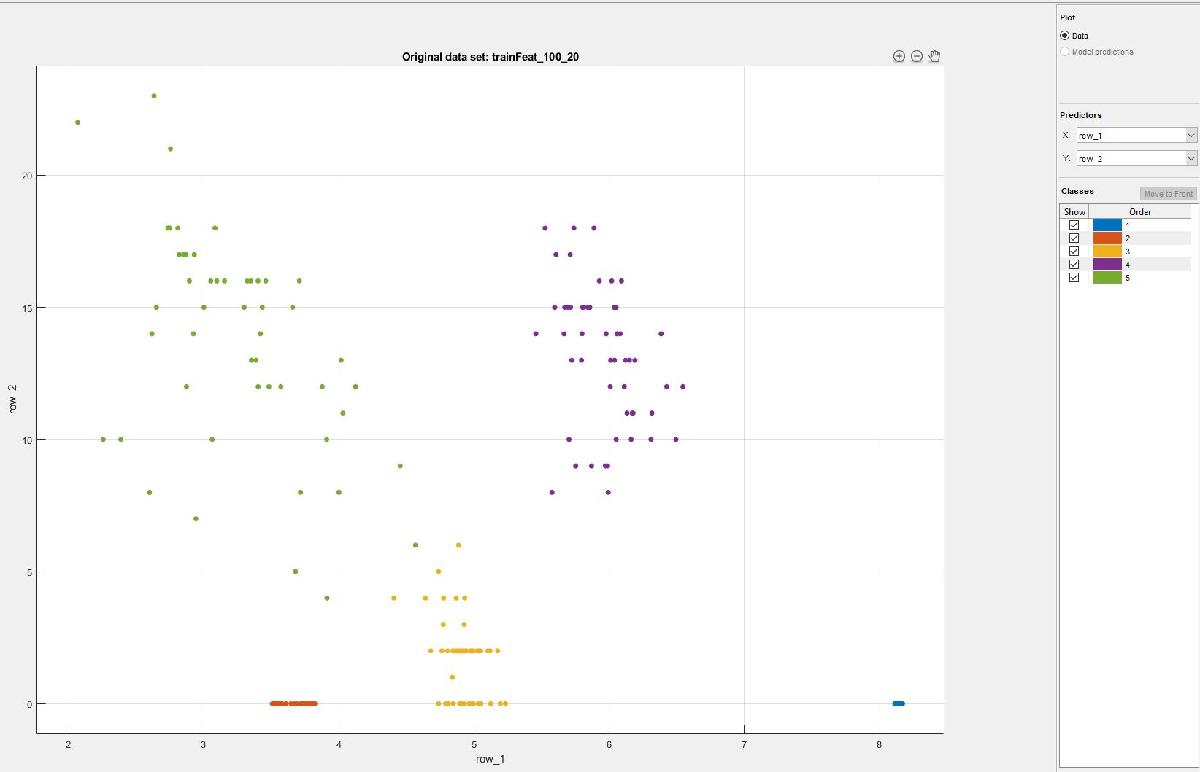

**Training 100/20 set across all classifiers, with no PCA and no normalization.**

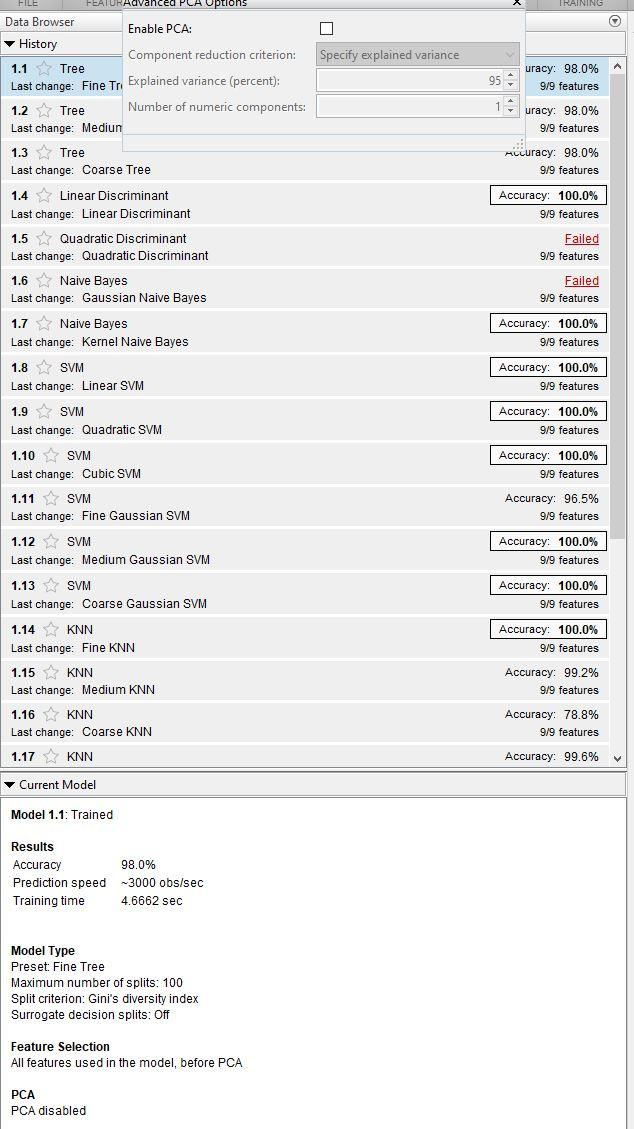

**Ran all classifiers with all the features to see highest accuracy possible. A lot achieved 100%**

**Example of Linear SVM of 100_20  trained model, with and without PCA.**